## TD 1 - IAR 2R FISA - 54 - Dr. MS JHA and Prof. D. THEILLIOL - 2022_2023 - Polytech Nancy / Universite de Lorraine

# TD1: Predicting Cancer  Using Shallow Neural Networks

Dataset: Breast Cancer Wisconsin (Diagnostic) Data Set 

**[Breast Cancer Wisconsin (Diagnostic) Data Set]** W.N. Street, W.H. Wolberg, and O.L. Mangasarian. Nuclear feature  extraction for breast tumor diagnosis. IS&T/SPIE 1993 International  Symposium on Electronic Imaging: Science and Technology, volume 1905,  pages 861–870, San Jose, CA, 1993. [link](https://archive.ics.uci.edu/ml/datasets/Breast+Cancer+Wisconsin+(Diagnostic))

Each feature in the **cancerInputs **variable describes cell attributes (adhesion, size, shape, etc).

The **cancerTargets **variable is encoded into 0 and 1, describing whether the cell was benign (0) or malignant (1).

# Data

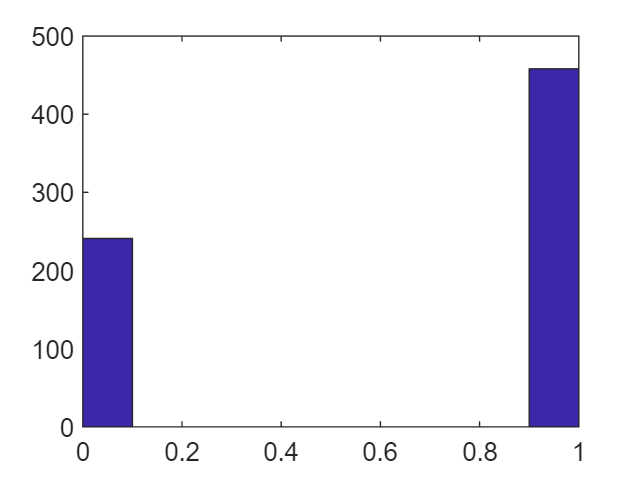

%load the dataset
clear all; close all
load cancer_dataset.mat

X = cancerInputs;
Y = cancerTargets;

% plot output data
figure(1);hist(Y(1,:));

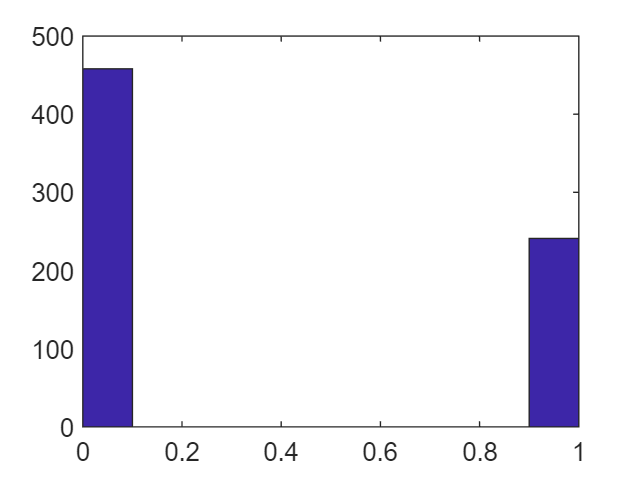

figure(1);hist(Y(2,:));

Observ that:

The data has already been processed so that minimum values are floored to 0.1, and maximum values are set to 1. 

Features should be spanning the rows, and the samples should span the columns

Train a simple shallow neural network classifier with **2 **nodes in the hidden layer. The output will be a 699 x 1 vector containing probabilities corresponding to cancer status.

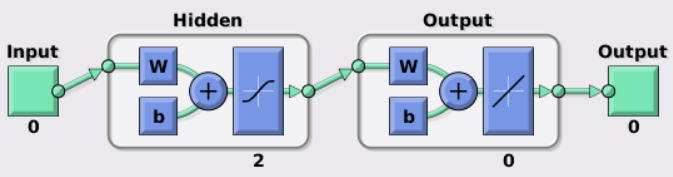

# ** Set up the network architecture**

we can use the [**patternnet **](https://www.mathworks.com/help/deeplearning/ref/patternnet.html)function (see the link, what is patternet? )

numOfActivationNodes = 2;        % 1 hidden layer with 2 activation nodes
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
net                  = patternnet(numOfActivationNodes, optimizationFnc)

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inp

`For information: `

[`net`](https://www.mathworks.com/help/deeplearning/ref/patternnet.html#mw_99478e34-faa8-4e57-9dc8-c181b5cbc8cd)` = patternnet(`[`hiddenSizes`](https://www.mathworks.com/help/deeplearning/ref/patternnet.html#mw_7cc02510-8d83-4496-b9e9-21c7afee7fcc)`,`[`trainFcn`](https://www.mathworks.com/help/deeplearning/ref/patternnet.html#mw_48d7230e-913c-4b48-9785-005d1e11de0c)`,`[`performFcn`](https://www.mathworks.com/help/deeplearning/ref/patternnet.html#mw_f3d1fafb-0df4-45fe-92ac-66ae04291eb3)`)`     returns a pattern recognition neural network with a hidden layer size of `hiddenSizes`, a training function, specified by `trainFcn`, and a performance function, specified by `performFcn`.

**net **is a model object that contains several modifiable properties that define the actions to be performed on the neural network.

A full description of neural network properties can be found [here](https://www.mathworks.com/help/deeplearning/ug/neural-network-object-properties.html)

Visualization can be done by

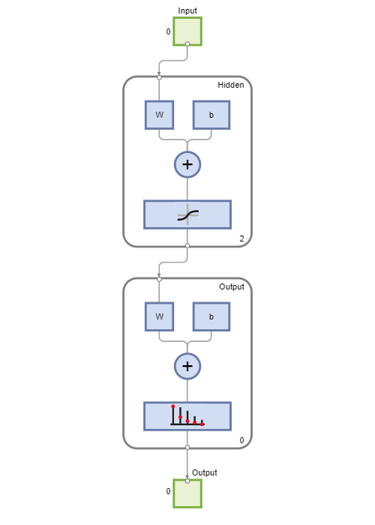

view(net) % Validation set size

# **Assign various  training and hyperparameters**

net.divideParam.trainRatio = 0.7; % Training set size
%net.divideParam.testRatio  = 0.0; % Test set size
net.divideParam.valRatio   = 0.3; % Validation set size
net.trainParam.epochs      = 5000;

This is a binary classification problem, the default loss  function is cross-entropy. 

To set the loss function manually, we can use the code below. 

IMPORTANT: Additional loss function arguments can be found [here](https://www.mathworks.com/help/deeplearning/ug/define-custom-training-loops-loss-functions-and-networks.html).

% Other options include:
  % softmax
  % sigmoid
  % mse
  
net.performFcn             = 'crossentropy';

# Training the model

Now we can use the [**train **](https://www.mathworks.com/help/deeplearning/ref/network.train.html)function to train the neural network. It outputs the trained neural network  object with 

additional properties and the record from training.

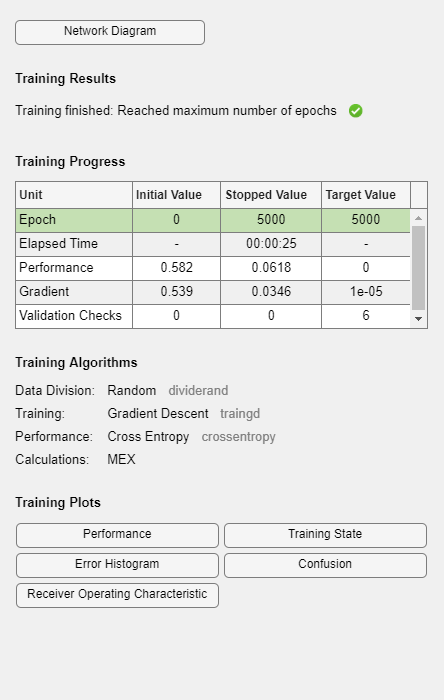

% trainedNet is the trained model object
% trainingRecord contains evaluation metrics w.r.t epochs
[trainedNet, trainingRecord] = train(net, X, Y);

An interactive UI will also pop up during the training phase.

For information:it performs **early stopping** to avoid  overfitting! So even if we specify a large number of epochs to train on, it will stop after the cost converges to a stable value.

# Computing the prediction error

The **trainedNet **object also acts as a method to make predictions and takes in the input  

dataset as an argument. We can also evaluate the model performance using the [**perform **](https://www.mathworks.com/help/deeplearning/ref/perform.html)function.

% Make a prediction
ypred = trainedNet(X);

% Compute error from cross-entropy
error = perform(trainedNet, Y, ypred);

# Visualizing and interpreting the model results

One diagnostic plot we can make is to visualize how the cost changes as a function of the number of epochs.

The cost computed from the training, validation, and test set seems to stabilize around 5,000 epochs.

figure;
plotperf(trainingRecord);

To evaluate the model accuracy, we can plot a confusion matrix of our predictions showing average accuracy using the **plotconfusion **function.

The diagonal cells are correct predictions while off-diagonal cells are  incorrect predictions.

 The values in the far-right column are the  precision while the bottom row contains the recall values. 

Overall, the  model had an accuracy which is not bad considering the number  of nodes in the hidden layer was selected arbitrarily without  optimization.

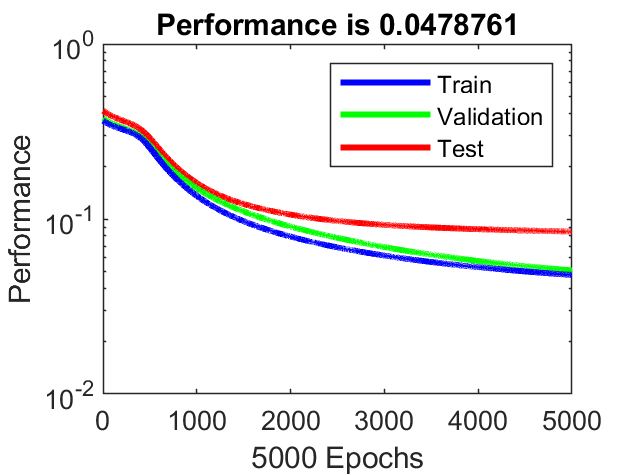

figure;
plotconfusion(ypred, Y);

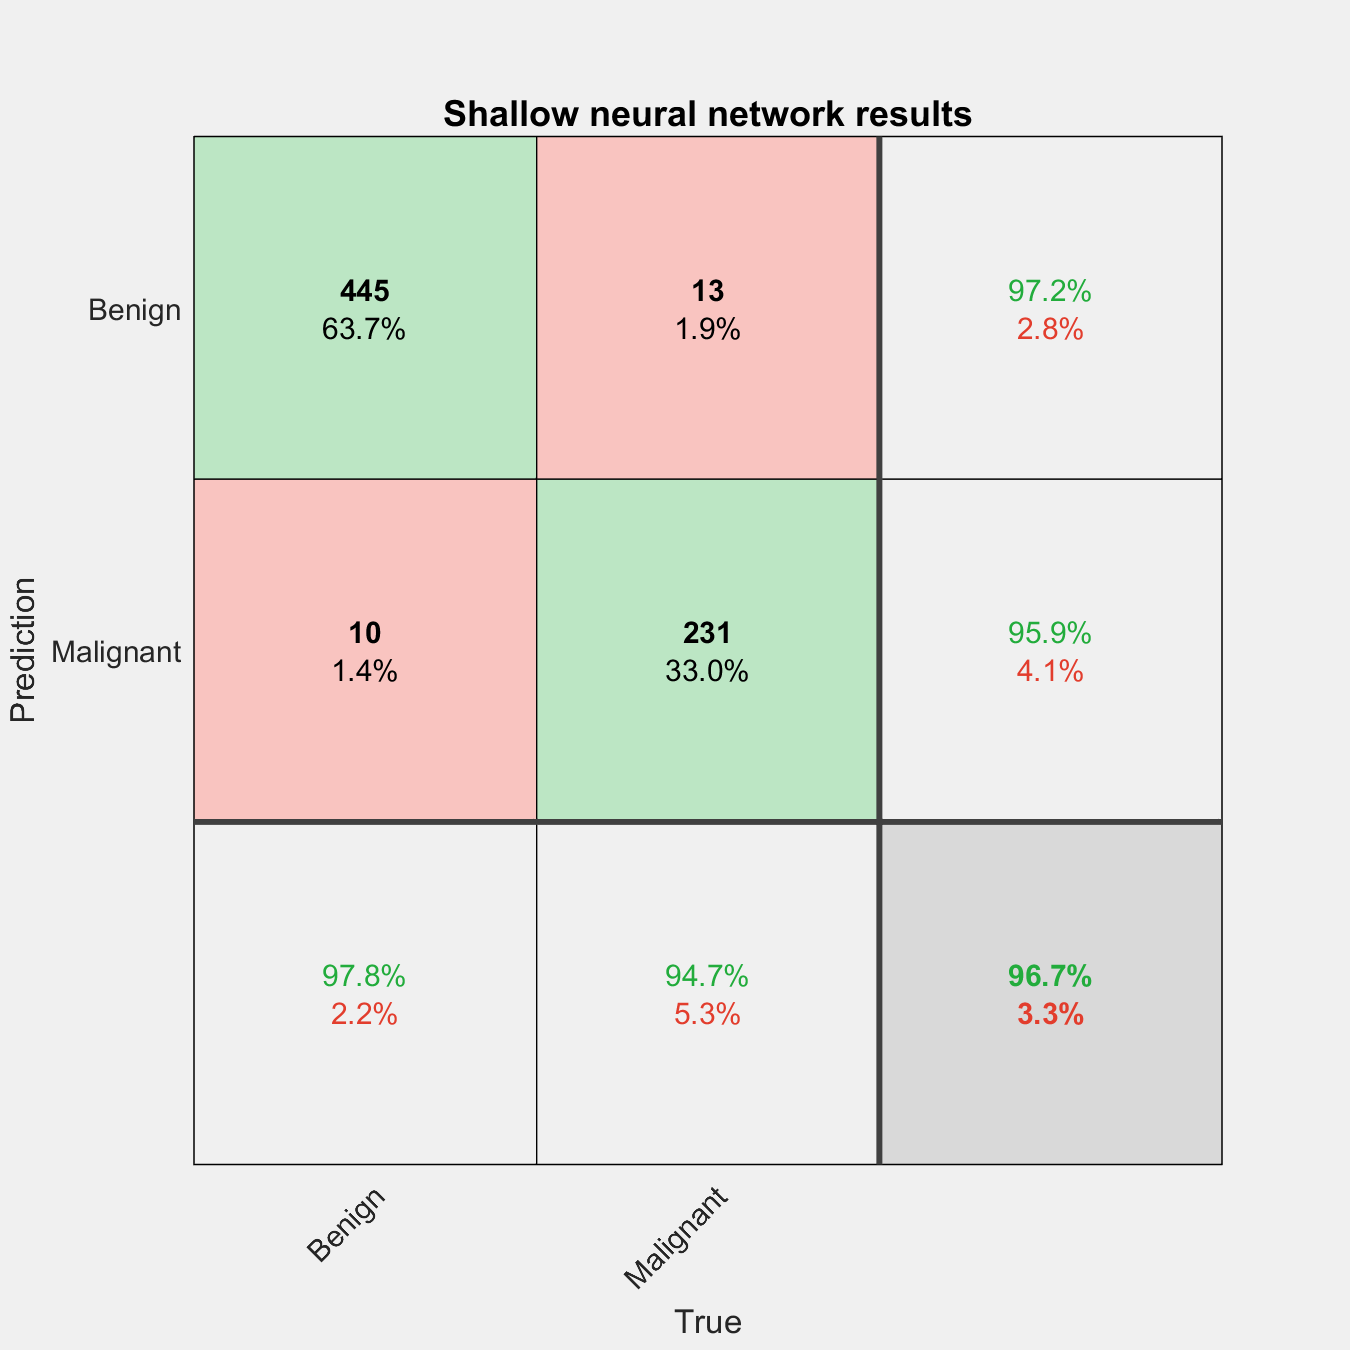

title("Shallow neural network results");
xlabel("True"); ylabel("Prediction");
xticklabels(["Benign", "Malignant"]);
yticklabels(["Benign", "Malignant"]);

# QUESTION about hyperparameter tuning with the Shallow Neural Network

Unfortunately, there is no built-in MATLAB function that performs hyperparameter  tuning on neural networks to obtain an optimal model as of this writing.

# Q1) Please consider some various number of nodes in the hidden layer (from 1 to 100), and provide a conclusion about the influence of nodes.

# Q2) Moreover, consider for an optimal number of nodes in the hidden layer, the influence of ratio between train data and validation data (from 0.05 to 0.95 % variations).

% the floor is yours !!!!